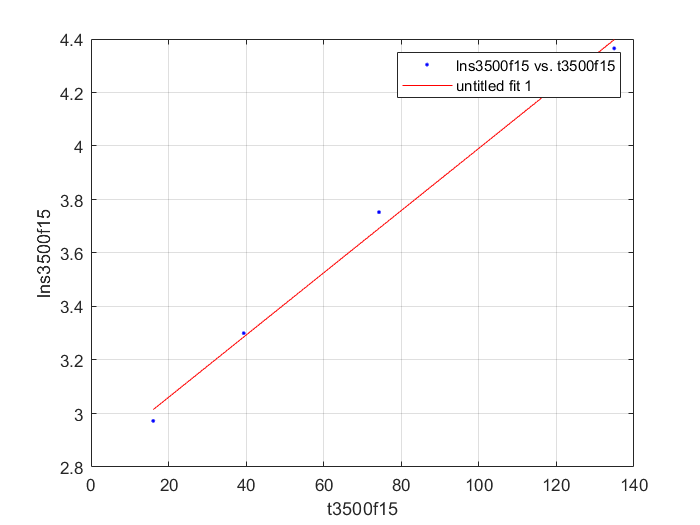

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( t3500f15, lns3500f15 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns3500f15 vs. t3500f15', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel t3500f15
ylabel lns3500f15
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01163  (0.008847, 0.01442)
 %      p2 =       2.828  (2.605, 3.051)

%Goodness of fit:
%  SSE: 0.006736
%  R-square: 0.9938
%  Adjusted R-square: 0.9908
%  RMSE: 0.05803